clear all

%!!!!guessed E is y!!

PermE = 8.854e-12;
PermH = 1.2566e-6;
c0 = 1/sqrt(PermH*PermE);

dz = 1;
dimZ = 100;

% min(min(dx,dy),dz)/(2*sqrt(PermE*PermH)) croissant time stablilty condition

% dt = .001;%1.66e-9
dt = dz*sqrt(PermE*PermH)/2

dt = 1.6678e-09

dimT = 3000;

dt*dimT

ans = 5.0033e-06

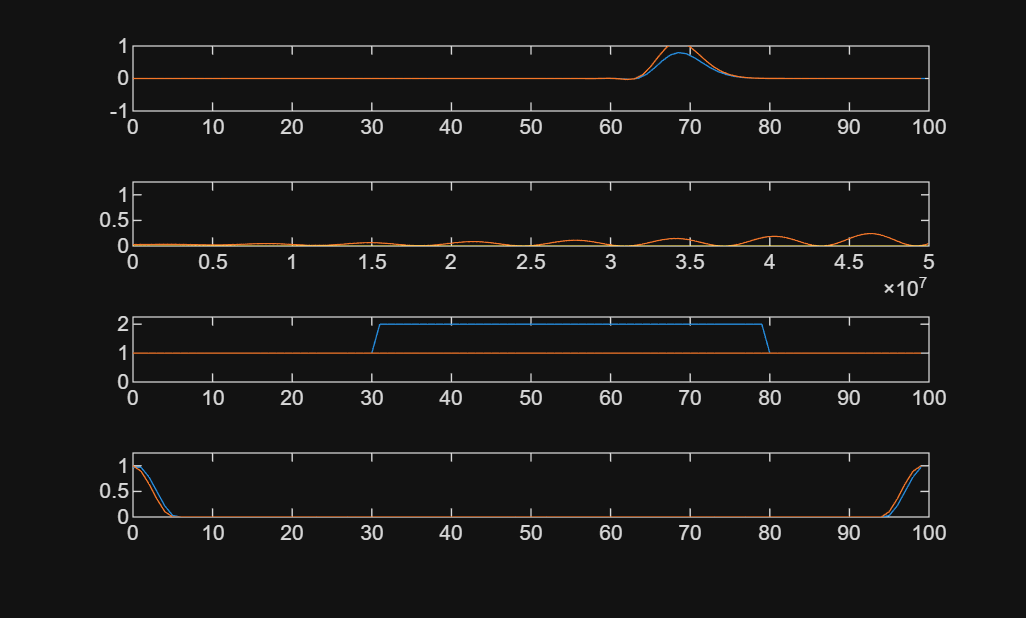


Gt = @(t) .5*exp(-(6e7*(t-5e-8)).^2);

dF = 5e4;
dimF = 1000;

dF*dimF;

T = linspace(0,(dimT-1)*dt,dimT);
Z = linspace(0,(dimZ-1)*dz,dimZ);
F = linspace(0,(dimF-1)*dF,dimF);
FK = exp(-complex(0,1)*2*pi*F*dt);
FG = 0*F;
FT = 0*F;
FR = 0*F;

Z0x = zeros(dimZ,1);

H    = Z0x;
E    = Z0x;
ICHX = Z0x;
ICEY = Z0x;
IHX  = Z0x;
IEY  = Z0x;

PermER0 = ones(dimZ,1);% scaled to make perm0 1
PermHR0 = ones(dimZ,1);% scaled to make perm0 1

PermERy = PermER0 + 1.0.*(Z<80&Z>30).';
PermHRx = PermHR0 + 0.0.*(Z<80&Z>30).';

PMLTK = 5;
alphaSIG = 3;
SFSIG  = .01;

SIGHZ = ((max(0,abs(Z-dimZ*dz/2)-((max(Z)-min(Z))/2-PMLTK)))/PMLTK)';
SIGEZ = ((max(0,abs(Z+dz/2-dimZ*dz/2)-((max(Z+dz/2)-min(Z+dz/2))/2-PMLTK)))/PMLTK)';
SIGHZ = SFSIG*(alphaSIG*SIGHZ.^(alphaSIG-1)-(alphaSIG-1)*SIGHZ.^alphaSIG);
SIGEZ = SFSIG*(alphaSIG*SIGEZ.^(alphaSIG-1)-(alphaSIG-1)*SIGEZ.^alphaSIG);

Hm0x = 1/dt + SIGHZ/(2*PermE);
Hm1x = (1/dt - SIGHZ/(2*PermE))./Hm0x;
Hm2x = -c0./( Hm0x.*PermHRx);
Hm3x = 0;
Hm4x = 0;
Em0y = 1/dt + SIGEZ/(2*PermE);
Em1y = (1/dt - SIGEZ/(2*PermE))./Em0y;
Em2y = -c0./( Em0y.*PermERy);
Em3y = 0;
Em4y = 0;

%deretive operators


D_zE = eye(dimZ)-diag(ones(dimZ-1,1),-1);
D_zE = D_zE/dz;

D_zH = diag(ones(dimZ-1,1),1)-eye(dimZ);
D_zH = D_zH/dz;

SFE = c0 * (dt ./ PermHRx);
SFH = c0 * (dt ./ PermERy);

SourceZ = 9;

subplot(4,1,1);
E_P = plot(Z+dz/2,E);
hold on
ylim([-1 1])
% pbaspect([5 1 1])
H_P = plot(Z,H);
subplot(4,1,2);
FG_P = plot(F,FG);
hold on
FT_P = plot(F,FT);
FR_P = plot(F,FR);
ylim([0 1.25])
subplot(4,1,3);
plot(Z,PermERy);
hold on
plot(Z,PermHRx);
ylim([0 2.25])
subplot(4,1,4);
plot(Z,SIGHZ*100);
hold on
plot(Z,SIGEZ*100);
ylim([0 1.25])
for i=1:dimT

    t = T(i); % Calculate the current time step

    ICEY = ICEY + (D_zE * E);
    ICHX = ICHX + (D_zH * H);

    IEY  =  IEY + E;
    IHX  =  IHX + H;

    E(SourceZ) = E(SourceZ) + Gt(t+.5*dz/c0-dt/2);
    H(SourceZ) = H(SourceZ) + Gt(t); 

    % Update the electric and magnetic fields using finite difference method

    H = Hm1x.*H + Hm2x.*(D_zE * E);
    E = Em1y.*E + Em2y.*(D_zH * H);

    % H = Hm1x.*H + Hm2x.*(D_zE * E) + Hm3x.*ICEY + Hm4x.*IHX;
    % E = Em1y.*E + Em2y.*(D_zH * H) + Em3y.*ICHX + Em4y.*IEY;

    % Update the plots
    set(E_P, 'YData', E);
    set(H_P, 'YData', H);
% Update frequency domain data
    FG = FG + Gt(t+.5*dz/c0-dt/2) .*FK.^i; 
    FT = FT - (E(07).*FK.^i); 
    FR = FR + (E(093).*FK.^i);

    set(FG_P, 'YData', .25*(abs(FR).^2+abs(FT).^2)./(abs(FG).^2));
    set(FT_P, 'YData', .25*(abs(FT).^2)./(abs(FG).^2));
    set(FR_P, 'YData', .25*(abs(FR).^2)./(abs(FG).^2));

    drawnow ;
end